# Workflow DES + Agua

**1. Importar los datos de viscosidad**

Visc_Mal=readtable("TFM\DATASET_TFM_DES_H2O.xlsx","Sheet","Visc_Maline","VariableNamingRule","preserve")

Visc_Mal = 172×11 table
        DES            Set Type        Condition      Mixture       Mass_percent_Water    Mass_percent_DES    Temperature(K)    Viscosity(Pa.s)    Viscosity(cP)         Reference          DES mole fraction
    ___________    ________________    _________    ____________    __________________    ________________    ______________    _______________    _____________    ____________________    _________________

    {'ChCl-MA'}    {'Experimental'}     {'QCM'}     {'Pure DES'}            0                    1                303.01             0.04766           47.66        {'(Barzinjy, 2016)'}     

Masa_H2O_Mal=Visc_Mal.Mass_percent_Water*100;
Temp_Mal=Visc_Mal.("Temperature(K)");
Mu_Mal=Visc_Mal.("Viscosity(cP)");
data=[Masa_H2O_Mal,Temp_Mal,Mu_Mal];

**2. Eliminación de outliers con función rmoultiers**

length(data)

ans = 172

data_def = rmoutliers(data); length(data_def)

ans = 144

data_median = rmoutliers(data,'median');length(data_median)

ans = 144

data_mean = rmoutliers(data,'mean');length(data_mean)

ans = 166

data_quart = rmoutliers(data,'quartiles');length(data_quart)

ans = 144

data_grubbs = rmoutliers(data,'grubbs');length(data_grubbs)

ans = 144

data_gesd = rmoutliers(data,'gesd');length(data_gesd)

ans = 153

Gráfica de datos de viscosidad con y sin outliers

Masa_H2O_Mal=Visc_Mal.Mass_percent_Water*100;
Temp_Mal=Visc_Mal.("Temperature(K)");
Mu_Mal=Visc_Mal.("Viscosity(cP)");
figure, plot3(Masa_H2O_Mal,Temp_Mal,Mu_Mal,'ob'); hold on
title('Viscosidad Reline + Agua - Datos procesados'), grid on,
xlabel('%Agua'), ylabel('Temp [K]'), zlabel('Visc. \mu [cP]'),
view([40 20])

Gráfica de datos sin outliers mean

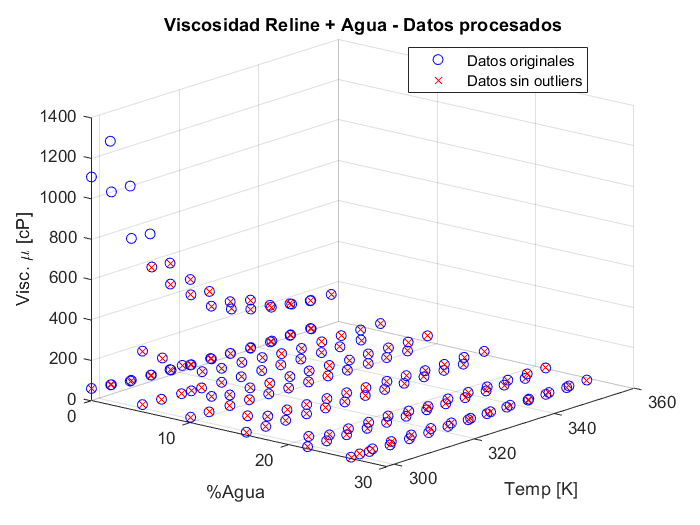

data_mean = rmoutliers(data,'mean');
plot3(data_mean(:,1),data_mean(:,2),data_mean(:,3),'xr')
legend('Datos originales', 'Datos sin outliers',"Location","best")
hold off

**3. División Conjuntos de Datos Entrenamiento y Prueba**

Masa_H2O_Mal=Visc_Mal.Mass_percent_Water*100;
Temp_Mal=Visc_Mal.("Temperature(K)");
Mu_Mal=Visc_Mal.("Viscosity(cP)");
data=[Masa_H2O_Mal,Temp_Mal,Mu_Mal];
data1=rmoutliers(data,'mean') % data1=rmoutliers(data,'grubbs');

data1 =          0  303.0141   47.6596
         0  307.7237   35.7447
         0  312.9042   32.7660
         0  317.7080   29.7872
         0  322.7943   20.8511
         0  327.8807   20.8511
         0  332.7786   14.8936
         0  337.8650    8.9362
         0  342.8571    8.9362
         0  347.9435   11.9149


min(data1(:,3))

ans = 0.3363

max(data1(:,3))

ans = 566.2602

n=length(data1);
particion=cvpartition(n,'HoldOut',0.2) % Se separa un 20% de datos para prueba

particion = Hold-out cross validation partition
   NumObservations: 166
       NumTestSets: 1
         TrainSize: 133
          TestSize: 33

Datos de entrenamiento

idx_train=training(particion);
train_data_visc1=data1(idx_train,:);

Masa_H2O_Eth_train=train_data_visc1(:,1);
Temp_Eth_train=train_data_visc1(:,2);
Mu_Eth_train=train_data_visc1(:,3);

Datos de prueba

idx_test=test(particion);
test_data_visc1=data1(idx_test,:);
Masa_H2O_Eth_test=test_data_visc1(:,1);
Temp_Eth_test=test_data_visc1(:,2);
Mu_Eth_test=test_data_visc1(:,3);

**4. Regresión fitlm**

predictores_train=[Masa_H2O_Eth_train Temp_Eth_train];
regre_visc_rel = fitlm(predictores_train,Mu_Eth_train)

regre_visc_rel = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)      408.98      153.2     2.6695      0.008566
    x1              -5.1243     0.8233    -6.2242    6.1709e-09
    x2             -0.86373    0.46369    -1.8627      0.064758


Number of observations: 133, Error degrees of freedom: 130
Root Mean Squared Error: 93.7
R-squared: 0.239,  Adjusted R-Squared: 0.227
F-statistic vs. constant model: 20.4, p-value = 2.03e-08

Ecuacion

coef1=table2array(regre_visc_rel.Coefficients(1,1));
coef2=table2array(regre_visc_rel.Coefficients(2,1));
coef3=table2array(regre_visc_rel.Coefficients(3,1));

fprintf('Ecuación')

Ecuación

fprintf('Viscosidad= %0.4f+(%0.4f)*%%Agua+(%0.4f)*Temperatura',coef1, coef2, coef3)

Viscosidad= 408.9758+(-5.1243)*%Agua+(-0.8637)*Temperatura

fprintf('Rango de porcentaje: %0.2f %% - %0.2f %%', min(Masa_H2O_Eth_train),max(Masa_H2O_Eth_train))

Rango de porcentaje: 0.00 % - 27.26 %

fprintf('Rango de temperatura: %0.2f K - %0.2f K', min(Temp_Eth_train),max(Temp_Eth_train))

Rango de temperatura: 297.90 K - 358.11 K

**4.1 Regresión toolbox**

predictores_train=[Masa_H2O_Eth_train Temp_Eth_train];
data_train_visc=[predictores_train Mu_Eth_train];
data_train_visc=array2table(data_train_visc,"VariableNames", ...
    {'Mass_percent_Water','Temperature(K)','Viscosity(cP)'})

data_train_visc = 133×3 table
    Mass_percent_Water    Temperature(K)    Viscosity(cP)
    __________________    ______________    _____________

            0                 303.01            47.66    
            0                 307.72           35.745    
            0                  312.9           32.766    
            0                 322.79           20.851    
            0                 332.78           14.894    
            0                 337.86           8.9362    
            0                 342.86           8.9362    
            0                 347.94           11.915    
            0                 352.94           11.915    
            0                 317.71           557.02    
            0                 322.79           443.83    
            0                  327.6           354.47    
            0                 332.78           271.06  


predictores_test=[Masa_H2O_Eth_test Temp_Eth_test];
data_test_visc=[predictores_test Mu_Eth_test];
data_test_visc=array2table(data_test_visc,"VariableNames", ...
    {'Mass_percent_Water','Temperature(K)','Viscosity(cP)'})

data_test_visc = 33×3 table
    Mass_percent_Water    Temperature(K)    Viscosity(cP)
    __________________    ______________    _____________

               0              317.71           29.787    
               0              327.88           20.851    
               0              328.06           278.86    
               0               347.8           9.9215    
               0               353.1           8.9126    
          5.0991              338.08           62.602    
          5.0877               343.2           62.602    
          5.1319              298.13           35.818    
          5.1098              307.99           27.578    
          10.068              312.93           79.675    
          10.041              317.93           71.138    
          10.014              323.05           71.138    
          9.9041              342.97           56.911    

[regre_visc_rel, validationRMSE] = Matern5_2GPR_Visc_Maline(data_train_visc)

regre_visc_rel = struct with fields:
           predictFcn: @(x)gpPredictFcn(predictorExtractionFcn(x))
    RequiredVariables: {'Mass_percent_Water'  'Temperature(K)'}
         RegressionGP: [1×1 RegressionGP]
                About: 'This struct is a trained model exported from Regression Learner R2021a.'
         HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to predict using an exported model.'


validationRMSE = 95.1877

regre_visc_rel.RegressionGP

ans =   RegressionGP
           PredictorNames: {'Mass_percent_Water'  'Temperature(K)'}
             ResponseName: 'Y'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 133
           KernelFunction: 'Matern52'
        KernelInformation: [1×1 struct]
            BasisFunction: 'Constant'
                     Beta: 72.3600
                    Sigma: 90.6934
        PredictorLocation: [2×1 double]
           PredictorScale: [2×1 double]
                    Alpha: [133×1 double]
         ActiveSetVectors: [133×2 double]
            PredictMethod: 'Exact'
            ActiveSetSize: 133
                FitMethod: 'Exact'
          ActiveSetMethod: 'Random'
        IsActiveSetVector: [133×1 logical]
            LogLikelihood: -796.1869
         ActiveSetHistory: []
           BCDInformation: []


  Properties, Method

regre_visc_rel.HowToPredict

ans =     'To make predictions on a new table, T, use: 
       yfit = c.predictFcn(T) 
     replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. 
      
     The table, T, must contain the variables returned by: 
       c.RequiredVariables 
     Variable formats (e.g. matrix/vector, datatype) must match the original training data. 
     Additional variables are ignored. 
      
     For more information, see How to predict using an exported model.'
